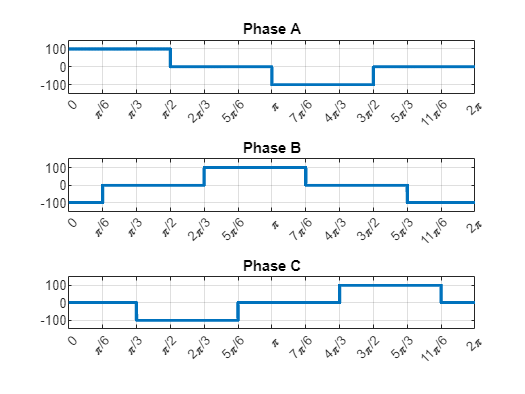

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%% Author: Hyeongmeen Baik, Dheerej
%%%%%%%%%%%% Date: 02/20/2024
%%%%%%%%%%%% Title: ECE 711 - HW3
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


clc;
clear all;

Ts=2^14;
wT=2*pi;
dwT=wT/Ts;
wt=dwT:dwT:wT;
a=exp(1i*2*pi/3);

vdc=100;

vas=vdc*(and((0<wt),(wt<=pi)))-vdc*(and((pi/2<wt),(wt<=pi)))-1*vdc*(and((pi<wt),(wt<=2*pi)))+vdc*(and((3*pi/2<wt),(wt<=2*pi)));
vbs=-1*vdc*(and((0<wt),(wt<=4*pi/6)))+vdc*(and((pi/6<wt),(wt<=2*pi/3)))+vdc*(and((2*pi/3<wt),(wt<=5*pi/3)))+-1*vdc*(and((7*pi/6<wt),(wt<=5*pi/3)))-1*vdc*(and((5*pi/3<wt),(wt<=2*pi)));
vcs=vdc*(and((0<wt),(wt<=pi/3)))-vdc*(and((0<wt),(wt<=4*pi/3)))+vdc*(and((5*pi/6<wt),(wt<=4*pi/3)))+vdc*(and((4*pi/3<wt),(wt<=2*pi)))-1*vdc*(and((11*pi/6<wt),(wt<=2*pi)));
figure;
subplot(311);plot(wt,vas,'LineWidth',2);grid;axis([0 2*pi -150 150]);
set(gca,'XTick',0:pi/6:2*pi);
set(gca,'XTickLabel',{'0','\pi/6','\pi/3','\pi/2','2\pi/3','5\pi/6','\pi','7\pi/6','4\pi/3','3\pi/2','5\pi/3','11\pi/6','2\pi'});
title('Phase A')

subplot(312);plot(wt,vbs,'LineWidth',2);grid;axis([0 2*pi -150 150]);
set(gca,'XTick',0:pi/6:2*pi);
set(gca,'XTickLabel',{'0','\pi/6','\pi/3','\pi/2','2\pi/3','5\pi/6','\pi','7\pi/6','4\pi/3','3\pi/2','5\pi/3','11\pi/6','2\pi'});
title('Phase B')

subplot(313);plot(wt,vcs,'LineWidth',2);grid;axis([0 2*pi -150 150]);
set(gca,'XTick',0:pi/6:2*pi);
set(gca,'XTickLabel',{'0','\pi/6','\pi/3','\pi/2','2\pi/3','5\pi/6','\pi','7\pi/6','4\pi/3','3\pi/2','5\pi/3','11\pi/6','2\pi'});
title('Phase C')

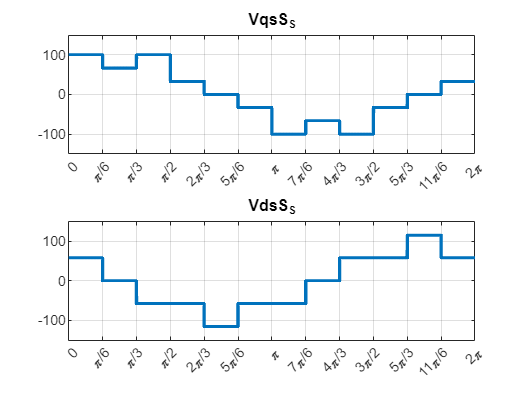


Vabcs=2/3*(vas+a*vbs+a^2*vcs);
vos= 1/3*(vas+vbs+vcs);

%DQ voltages
Vqs_s=real(Vabcs);
Vds_s=-imag(Vabcs);
Vqd=abs(Vabcs(1));
figure
subplot(211);plot(wt,Vqs_s,'LineWidth',2);grid;axis([0 2*pi -150 150]);
set(gca,'XTick',0:pi/6:2*pi);
set(gca,'XTickLabel',{'0','\pi/6','\pi/3','\pi/2','2\pi/3','5\pi/6','\pi','7\pi/6','4\pi/3','3\pi/2','5\pi/3','11\pi/6','2\pi'});
title('VqsS_S')

subplot(212);plot(wt,Vds_s,'LineWidth',2);grid;axis([0 2*pi -150 150]);
set(gca,'XTick',0:pi/6:2*pi);
set(gca,'XTickLabel',{'0','\pi/6','\pi/3','\pi/2','2\pi/3','5\pi/6','\pi','7\pi/6','4\pi/3','3\pi/2','5\pi/3','11\pi/6','2\pi'});
title('VdsS_S')

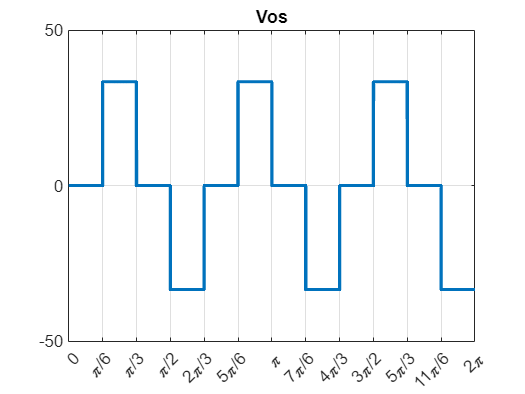


figure
plot(wt,vos,'LineWidth',2);grid;axis([0 2*pi -50 50]);
set(gca,'XTick',0:pi/6:2*pi);
set(gca,'XTickLabel',{'0','\pi/6','\pi/3','\pi/2','2\pi/3','5\pi/6','\pi','7\pi/6','4\pi/3','3\pi/2','5\pi/3','11\pi/6','2\pi'});
title('Vos')


%Rms of waveforms 
Vqs_rms=rms(Vqs_s)

Vqs_rms = 66.6687

Vds_rms=rms(Vds_s)

Vds_rms = 66.6646

Vos_rms=rms(vos)

Vos_rms = 23.5702


%FFT of waveform to get fundamental frequency
f1=fft(Vqs_s,Ts);
Vqs_sfft=(2*abs(f1(2))/Ts)/sqrt(2)

Vqs_sfft = 63.6643


f2=fft(Vds_s,Ts);
Vds_sfft=(2*abs(f2(2))/Ts)/sqrt(2)

Vds_sfft = 63.6596

b)Plotting the trajectory

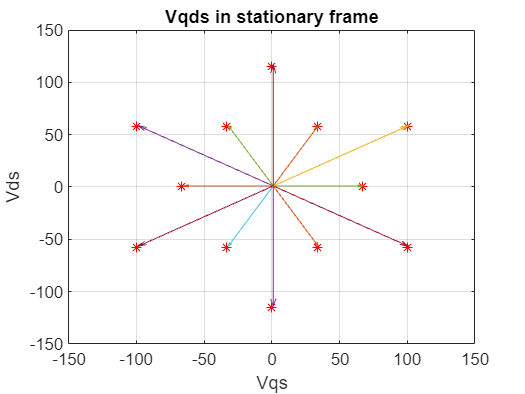

iter=2^6;
steps=Ts/iter;

%stator frame
figure;
plot(Vqs_s,Vds_s,'*r');grid on;hold on;
axis([-150 150 -150 150]);
title('Vqds in stationary frame');ylabel('Vds');xlabel('Vqs');

for k=1:steps:Ts
     quiver(Vqs_s(k),-Vds_s(k),'AutoScale','off');grid on;
     drawnow

end

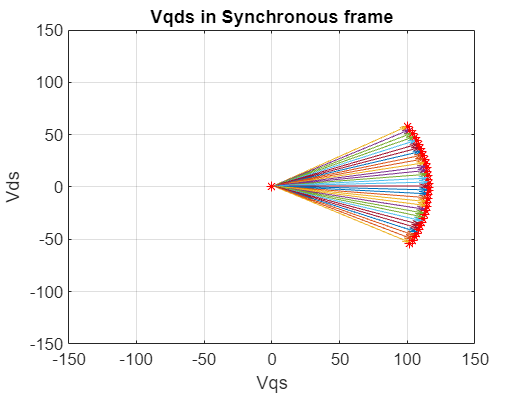


%synchronous frame

Vqds=zeros(1,iter);

for k=1:steps:Ts
    theta=mod(wt(k),pi/3)-pi/6;
    Vqds(k)=Vqd*(cos(theta)-1i*sin(theta));

end

figure;
plot(Vqds,'*r');grid on;hold on;
axis([-150 150 -150 150]);
title('Vqds in Synchronous frame');ylabel('Vds');xlabel('Vqs');

for k=1:steps:Ts
     theta=mod(wt(k),pi/3)-pi/6;
     Vqds(k)=Vqd*(cos(theta)-1i*sin(theta));
     quiver(Vqd*cos(theta),-Vqd*sin(theta),'AutoScale','off');grid on;
     set(gca,'xlim',[-150 150],'ylim',[-150 150]);
     drawnow
     hold on
     plot(Vqds,'.r')
end
hold off;

Part C

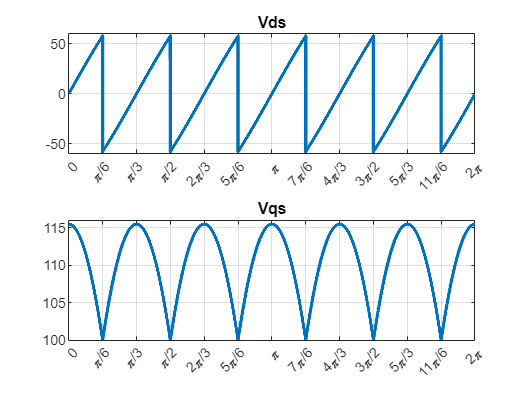

Vds_e(1:Ts)=0;
Vqs_e(1:Ts)=0;

for k=1:Ts
   if(wt(k)<pi/6)
        theta=mod(wt(k),pi/3);
   else
       theta=(mod(wt(k)+pi/6,pi/3)-pi/6);
   end
   Vds_e(k)=Vqd*sin(theta);
   Vqs_e(k)=Vqd*cos(theta);
end

figure
subplot(211);plot(wt,Vds_e,'LineWidth',2);grid;axis([0 2*pi -60 60]);
set(gca,'XTick',0:pi/6:2*pi);
set(gca,'XTickLabel',{'0','\pi/6','\pi/3','\pi/2','2\pi/3','5\pi/6','\pi','7\pi/6','4\pi/3','3\pi/2','5\pi/3','11\pi/6','2\pi'});
title('Vds')

subplot(212);plot(wt,Vqs_e,'LineWidth',2);grid;axis([0 2*pi 100 116]);
set(gca,'XTick',0:pi/6:2*pi);
set(gca,'XTickLabel',{'0','\pi/6','\pi/3','\pi/2','2\pi/3','5\pi/6','\pi','7\pi/6','4\pi/3','3\pi/2','5\pi/3','11\pi/6','2\pi'});
title('Vqs')

Part D

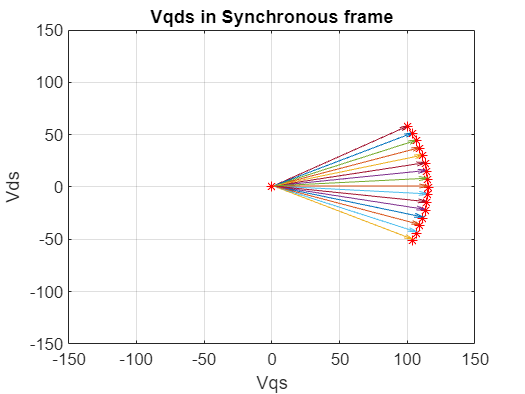


%synchronous frame

Vqds=zeros(1,iter);

for k=1:steps:Ts
    theta=mod(2*wt(k),pi/3)-pi/6;
    Vqds(k)=Vqd*(cos(theta)-1i*sin(theta));

end

figure;
plot(Vqds,'*r');grid on;hold on;
axis([-150 150 -150 150]);
title('Vqds in Synchronous frame');ylabel('Vds');xlabel('Vqs');

for k=1:steps:Ts
     theta=mod(2*wt(k),pi/3)-pi/6;
     Vqds(k)=Vqd*(cos(theta)-1i*sin(theta));
     quiver(Vqd*cos(theta),-Vqd*sin(theta),'AutoScale','off');grid on;
     set(gca,'xlim',[-150 150],'ylim',[-150 150]);
     drawnow
     hold on
     plot(Vqds,'.r')
end
hold off;

clc
clear
close all

theta_diff = 1e-5

theta_diff = 1.0000e-05

theta = 0:theta_diff:2*pi-theta_diff;
a_signal = sin(theta);
hi = abcgenerator(a_signal,theta);
a_rot = exp(1*j*2*pi/3);

VDC = 100;
vas = VDC*(and(theta>=0,theta<pi/2)-and(pi<=theta,theta<3*pi/2));
vs = abcgenerator(vas,theta);
Vabcs = 2/3*(vs.a+vs.b*a_rot+vs.c*a_rot^2);
vs.o = 1/3*(vs.a+vs.b+vs.c);

vs.q = real(Vabcs);
vs.d = -imag(Vabcs);
vs.qd = abs(Vabcs(1));

% RMS
vs.a_rms = rms(vs.a)

vs = struct with fields:
        b: [-100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 … ]
        c: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
        a: [100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 … ]
        o: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

vs.q_rms = rms(vs.q)

vs = struct with fields:
        b: [-100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 … ]
        c: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
        a: [100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 … ]
        o: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

vs.d_rms = rms(vs.d)

vs = struct with fields:
        b: [-100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 … ]
        c: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
        a: [100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 … ]
        o: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

vs.o_rms = rms(vs.o)

vs = struct with fields:
        b: [-100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 -100 … ]
        c: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
        a: [100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 100 … ]
        o: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 

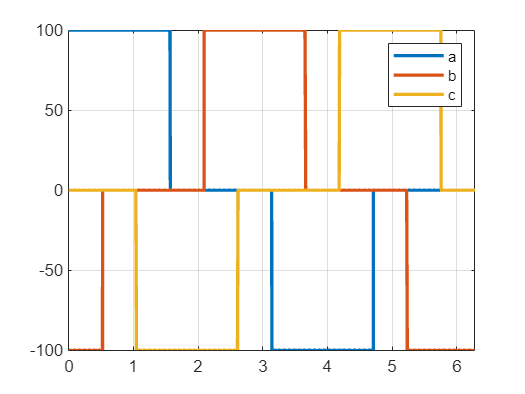



% figure(100)
% plot(theta,hi.a,'DisplayName','a','LineWidth',2);hold on; grid on;legend
% plot(theta,hi.b,'DisplayName','b','LineWidth',2)
% plot(theta,hi.c,'DisplayName','c','LineWidth',2)
% xlim([0 2*pi])

figure(1)
plot(theta,vs.a,'DisplayName','a','LineWidth',2);hold on; grid on;legend
plot(theta,vs.b,'DisplayName','b','LineWidth',2)
plot(theta,vs.c,'DisplayName','c','LineWidth',2)
xlim([0 2*pi])
hold off;

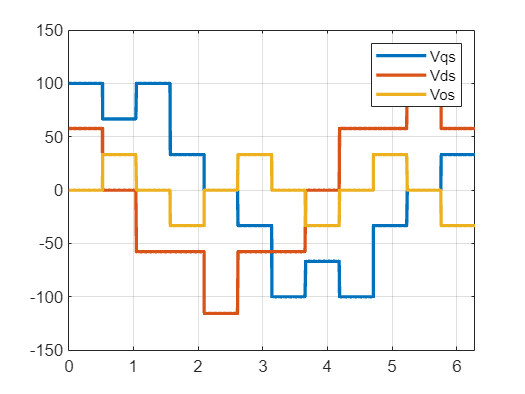


figure(2)
plot(theta,vs.q,'DisplayName','Vqs','LineWidth',2);hold on; grid on;legend
plot(theta,vs.d,'DisplayName','Vds','LineWidth',2)
plot(theta,vs.o,'DisplayName','Vos','LineWidth',2)
xlim([0 2*pi])
hold off;

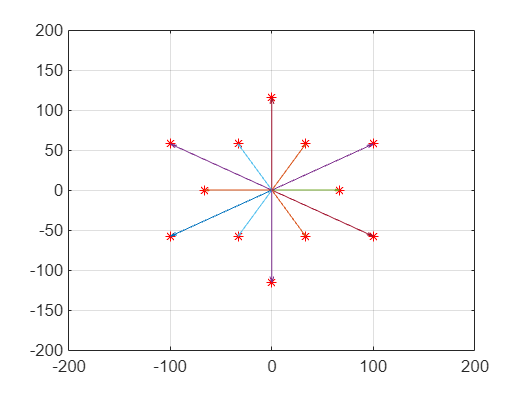


%% b)
iter = 2^6;
steps = fix(length(theta)/iter);

% Stationary frame
figure(21);
plot(vs.q,vs.d,'*r');grid on; hold on
axis([-200 200 -200 200]);

for k = 1:1:iter
    quiver(0,0,vs.q((k-1)*steps+1),-vs.d((k-1)*steps+1),'AutoScale','off');
    drawnow
end
hold off;

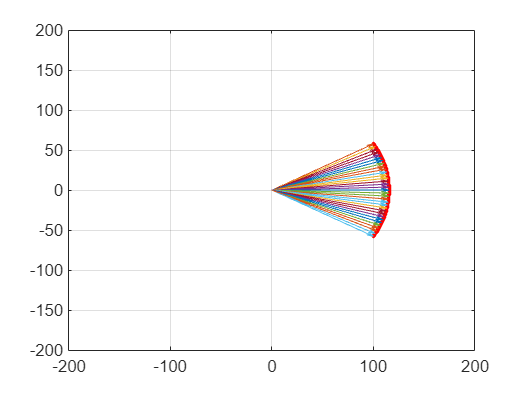


% synchronous frame
% electrical frame
theta_sync = mod(theta,pi/3)-pi/6;
Vqds = vs.qd*(cos(theta_sync)-1j*sin(theta_sync));

figure(22);
plot(Vqds,'.r');grid on; hold on
axis([-200 200 -200 200]);

for k = 1:1:iter
    quiver(0,0,vs.qd*cos(theta_sync((k-1)*steps+1)),-vs.qd*sin(theta_sync((k-1)*steps+1)),'AutoScale','off');
    drawnow
end
hold off;

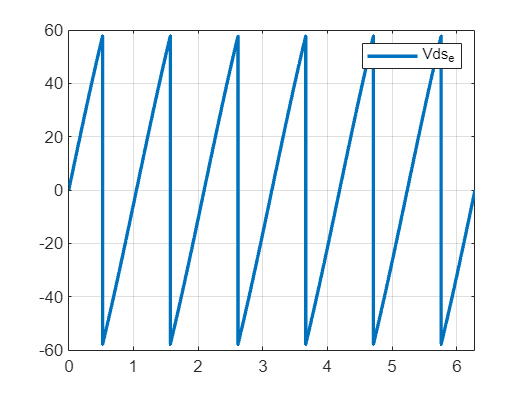



%% c)
Vds_e = zeros(size(theta_sync));
Vqs_e = zeros(size(theta_sync));

for k = 1:1:length(theta_sync)
    if theta(1,k) < pi/6
        theta_temp = mod(theta(1,k),pi/3);
    else
        theta_temp = mod(theta(1,k)+pi/6,pi/3)-pi/6;
    end
    Vds_e(1,k) = vs.qd*sin(theta_temp);
    Vqs_e(1,k) = vs.qd*cos(theta_temp);
end

figure(31)
plot(theta,Vds_e,'DisplayName','Vds_e','LineWidth',2);hold on; grid on;legend
xlim([0 2*pi])
hold off;

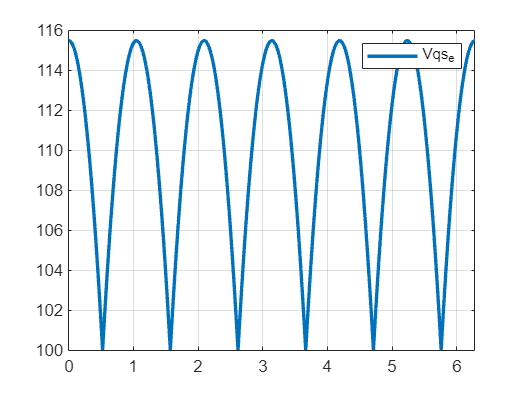


figure(32)
plot(theta,Vqs_e,'DisplayName','Vqs_e','LineWidth',2);hold on; grid on;legend
xlim([0 2*pi])
hold off;

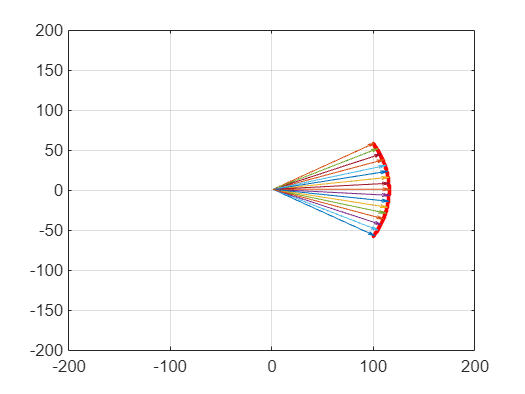


%% d)
% synchronous frame
% twice of electrical frame
theta_double_sync = mod(2*theta,pi/3)-pi/6;
Vqds_double = vs.qd*(cos(theta_double_sync)-1j*sin(theta_double_sync));

figure(41);
plot(Vqds_double,'.r');grid on; hold on
axis([-200 200 -200 200]);

for k = 1:1:iter
    quiver(vs.qd*cos(theta_double_sync((k-1)*steps+1)),-vs.qd*sin(theta_double_sync((k-1)*steps+1)),'AutoScale','off');
    drawnow
end
hold off;

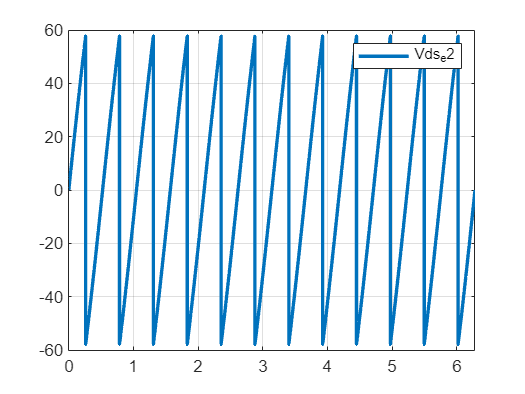


Vds_e2 = zeros(size(theta_sync));
Vqs_e2 = zeros(size(theta_sync));

for k = 1:1:length(theta_sync)
    if 2*theta(1,k) < pi/6
        theta_temp = mod(2*theta(1,k),pi/3);
    else
        theta_temp = mod(2*theta(1,k)+pi/6,pi/3)-pi/6;
    end
    Vds_e2(1,k) = vs.qd*sin(theta_temp);
    Vqs_e2(1,k) = vs.qd*cos(theta_temp);
end

figure(42)
plot(theta,Vds_e2,'DisplayName','Vds_e2','LineWidth',2);hold on; grid on;legend
xlim([0 2*pi])
hold off;

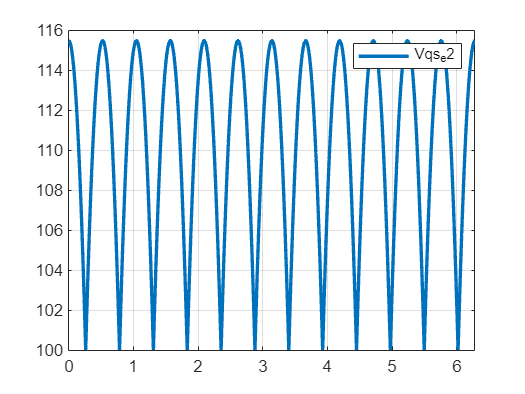


figure(43)
plot(theta,Vqs_e2,'DisplayName','Vqs_e2','LineWidth',2);hold on; grid on;legend
xlim([0 2*pi])
hold off;


%% e)
% Due to non-ideality coming from window method of fft, lengthy input
% signal is essential to have less window error.
iter_array = 100

iter_array = 100

theta_long = unwrap(horzcat(theta,iter_array));
Vabcs_long = horzcat(Vabcs,iter_array);

Ts = theta_long(1,2) - theta_long(1,1);
Fs = 1/Ts;
f = Fs/length(theta_long)*(0:length(theta_long)-1);

vs.q_fft = fft(real(Vabcs_long));
vs.d_fft = fft(-imag(Vabcs_long));

% For detailed operation, look into the function below
[Vabcs1 fund_freq] = harmonic_extract(Vabcs_long,theta_long,1);

target_freq = 0.1592

ans = 4.0000e+07 - 4.0000e+07i

vs.q1 = real(Vabcs1);
vs.d1 = -imag(Vabcs1);
vs.qd1 = abs(Vabcs1(1));
vs.q_fft1 = fft(real(Vabcs1));
vs.d_fft1 = fft(-imag(Vabcs1));
vs.phase_angle1 = angle(Vabcs1(1,1));
sign(angle(vs.q1(1,2) - j*vs.d1(1,2))-angle(vs.q1(1,1) - j*vs.d1(1,1)))

ans = 1



Vabcs3 = harmonic_extract(Vabcs_long,theta_long,3);

target_freq = 0.4775

ans = 2.0516e+02 + 2.0627e+01i

vs.q3 = real(Vabcs3);
vs.d3 = -imag(Vabcs3);
vs.qd3 = abs(Vabcs3(1));
vs.q_fft3 = fft(real(Vabcs3));
vs.d_fft3 = fft(-imag(Vabcs3));
vs.phase_angle3 = angle(Vabcs3(1,1));
sign(angle(vs.q3(1,2) - j*vs.d3(1,2))-angle(vs.q3(1,1) - j*vs.d3(1,1)))

ans = -1


Vabcs5 = harmonic_extract(Vabcs_long,theta_long,5);

target_freq = 0.7958

ans = 2.0515e+02 + 9.4844e+01i

vs.q5 = real(Vabcs5);
vs.d5 = -imag(Vabcs5);
vs.qd5 = abs(Vabcs5(1));
vs.q_fft5 = fft(real(Vabcs5));
vs.d_fft5 = fft(-imag(Vabcs5));
vs.phase_angle5 = angle(Vabcs5(1,1));
sign(angle(vs.q5(1,2) - j*vs.d5(1,2))-angle(vs.q5(1,1) - j*vs.d5(1,1)))

ans = -1


Vabcs7 = harmonic_extract(Vabcs_long,theta_long,7);

target_freq = 1.1141

ans = -5.7143e+06 - 5.7142e+06i

vs.q7 = real(Vabcs7);
vs.d7 = -imag(Vabcs7);
vs.qd7 = abs(Vabcs7(1));
vs.q_fft7 = fft(real(Vabcs7));
vs.d_fft7 = fft(-imag(Vabcs7));
vs.phase_angle7 = angle(Vabcs7(1,1));
sign(angle(vs.q7(1,2) - j*vs.d7(1,2))-angle(vs.q7(1,1) - j*vs.d7(1,1)))

ans = 1


Vabcs9 = harmonic_extract(Vabcs_long,theta_long,9);

target_freq = 1.4324

ans = 1.2818e+02 + 2.8730e+02i

vs.q9 = real(Vabcs9);
vs.d9 = -imag(Vabcs9);
vs.qd9 = abs(Vabcs9(1));
vs.q_fft9 = fft(real(Vabcs9));
vs.d_fft9 = fft(-imag(Vabcs9));
vs.phase_angle9 = angle(Vabcs9(1,1));
sign(angle(vs.q9(1,2) - j*vs.d9(1,2))-angle(vs.q9(1,1) - j*vs.d9(1,1)))

ans = 1


Vabcs11 = harmonic_extract(Vabcs_long,theta_long,11);

target_freq = 1.7507

ans = 1.2816e+02 - 1.7182e+02i

vs.q11 = real(Vabcs11);
vs.d11 = -imag(Vabcs11);
vs.qd11 = abs(Vabcs11(1));
vs.q_fft11 = fft(real(Vabcs11));
vs.d_fft11 = fft(-imag(Vabcs11));
vs.phase_angle11 = angle(Vabcs11(1,1));
sign(angle(vs.q11(1,2) - j*vs.d11(1,2))-angle(vs.q11(1,1) - j*vs.d11(1,1)))

ans = -1


Vabcs13 = harmonic_extract(Vabcs_long,theta_long,13);

target_freq = 2.0690

ans = 3.0769e+06 - 3.0769e+06i

vs.q13 = real(Vabcs13);
vs.d13 = -imag(Vabcs13);
vs.qd13 = abs(Vabcs13(1));
vs.q_fft13 = fft(real(Vabcs13));
vs.d_fft13 = fft(-imag(Vabcs13));
vs.phase_angle13 = angle(Vabcs13(1,1));
sign(angle(vs.q13(1,2) - j*vs.d13(1,2))-angle(vs.q13(1,1) - j*vs.d13(1,1)))

ans = 1


Vabcs19 = harmonic_extract(Vabcs_long,theta_long,19);

target_freq = 3.0239

ans = -2.1053e+06 - 2.1051e+06i

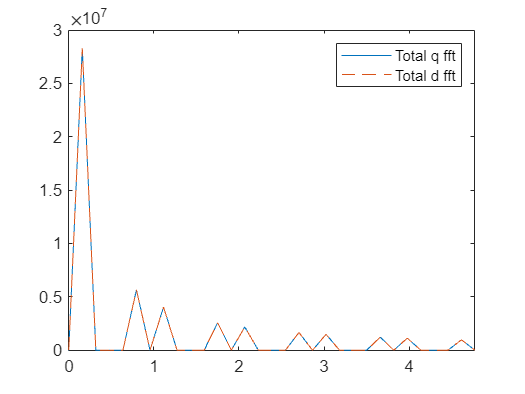

vs.q19 = real(Vabcs19);
vs.d19 = -imag(Vabcs19);
vs.qd19 = abs(Vabcs19(1));
vs.q_fft19 = fft(real(Vabcs19));
vs.d_fft19 = fft(-imag(Vabcs19));
vs.phase_angle19 = angle(Vabcs19(1,1));

figure(50)
plot(f,abs(vs.q_fft),'DisplayName','Total q fft');hold on;legend;
plot(f,abs(vs.d_fft),'--','DisplayName','Total d fft');hold off
xlim([0 30*fund_freq])

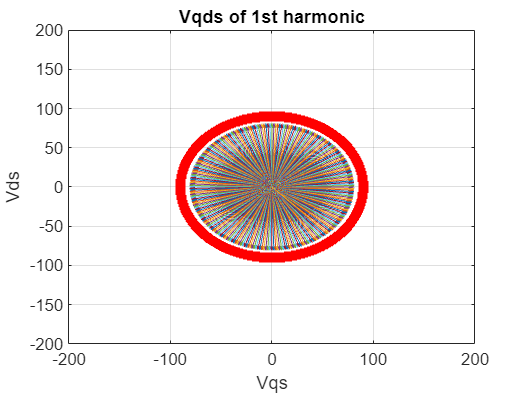


%%
vs.fft1 = abs(vs.q_fft1-j*vs.d_fft1);
vs.fft3 = abs(vs.q_fft3-j*vs.d_fft3);
vs.fft5 = abs(vs.q_fft5-j*vs.d_fft5);
vs.fft7 = abs(vs.q_fft7-j*vs.d_fft7);
vs.fft9 = abs(vs.q_fft9-j*vs.d_fft9);
vs.fft11 = abs(vs.q_fft11-j*vs.d_fft11);
vs.fft13 = abs(vs.q_fft13-j*vs.d_fft13);



% figure(51)
% stem(f,vs.fft1,'DisplayName','fft fundamental');hold on;legend
% stem(f,vs.fft3,'DisplayName','3rd harmonic')
% stem(f,vs.fft5,'DisplayName','5th harmonic')
% stem(f,vs.fft7,'DisplayName','7th harmonic')
% stem(f,vs.fft9,'DisplayName','9th harmonic')
% stem(f,vs.fft11,'DisplayName','11th harmonic')
% stem(f,vs.fft13,'DisplayName','13th harmonic')
% xlim([0 20*fund_freq])
%%
figure(52)
plot(vs.q1,vs.d1); hold on
plot(vs.q7,vs.d7);
plot(vs.q11,vs.d11);
plot(vs.q13,vs.d13);
plot(vs.q19,vs.d19);


iter = 2^8;
steps = fix(length(theta_long)/iter);
% Stationary frame
figure(53);
plot(vs.q1,vs.d1,'*r');grid on; hold on
axis([-200 200 -200 200]);
title('Vqds of 1st harmonic');ylabel('Vds');xlabel('Vqs');
for k = 1:1:iter
    quiver(0,0,vs.q1(1,(k-1)*steps+1),-vs.d1(1,(k-1)*steps+1));
    drawnow
end
hold off;

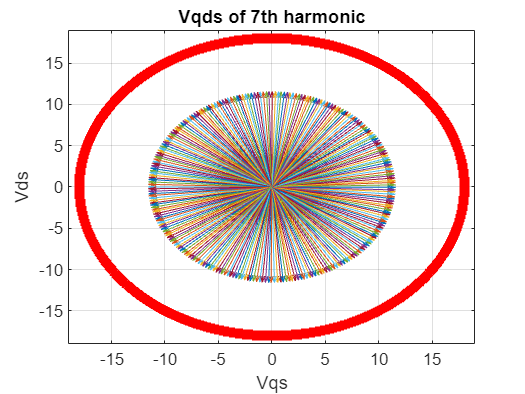


figure(54);
plot(vs.q5,vs.d5,'*r');grid on; hold on
axis([-19 19 -19 19]);
title('Vqds of 7th harmonic');ylabel('Vds');xlabel('Vqs');
for k = 1:1:iter
    quiver(0,0,vs.q7(1,(k-1)*steps+1),-vs.d7(1,(k-1)*steps+1));
    drawnow
end
hold off;

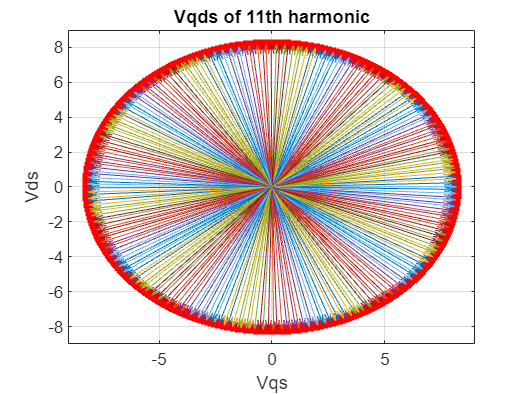


figure(55);
plot(vs.q11,vs.d11,'*r');grid on; hold on
axis([-9 9 -9 9]);
title('Vqds of 11th harmonic');ylabel('Vds');xlabel('Vqs');
for k = 1:1:iter
    quiver(0,0,vs.q11(1,(k-1)*steps+1),-vs.d11(1,(k-1)*steps+1),'AutoScale','off');
    drawnow
end
hold off;

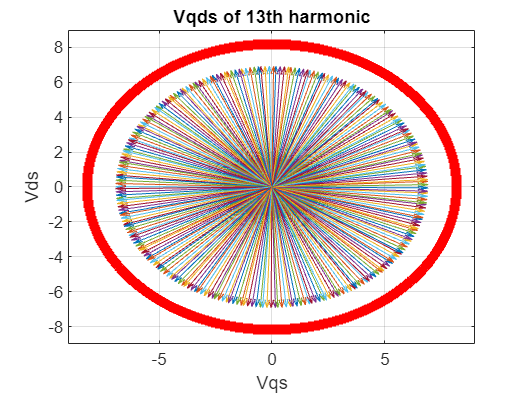


figure(56);
plot(vs.q11,vs.d11,'*r');grid on; hold on
axis([-9 9 -9 9]);
title('Vqds of 13th harmonic');ylabel('Vds');xlabel('Vqs');
for k = 1:1:iter
    quiver(0,0,vs.q13(1,(k-1)*steps+1),-vs.d13(1,(k-1)*steps+1),'AutoScale','off');
    drawnow
end
hold off;


%%
%% functions

function [out fund_freq] = harmonic_extract(time_signal, theta, order)
    X_fft = fft(time_signal);
    [M fund_index] = max(fft(time_signal));
    
    Ts = theta(1,2) - theta(1,1);
    Fs = 1/Ts;
    f = linspace(0,Fs,length(theta));
    % fund_freq = f(1,fund_index) 
    fund_freq = 1/2/pi;                 %mentioning fundamental frequency improves estimating accuracy
    target_freq = fund_freq*order
    i1_1 = find(f>=fund_freq*order,1);
    i1_2 = length(f)-i1_1+2;
    X_fft(1,i1_1)
    
    X_fft_extract = zeros(size(X_fft));
    X_fft_extract(1,i1_1) = X_fft(1,i1_1);
    X_fft_extract(1,i1_2) = X_fft(1,i1_2);


    out = ifft(X_fft_extract);
end
% fundamental
function out = fund_extract(Nsa,Ps,theta)
    % fundamental self inductance
    C_pos1 = 1/2/sym(pi)*int(Nsa*exp(-j*theta*2/Ps),0,2*pi);
    C_neg1 = 1/2/sym(pi)*int(Nsa*exp(j*theta*2/Ps),0,2*pi);
    k = sqrt((C_pos1+C_neg1)^2+(j*C_pos1-j*C_neg1)^2);
    if C_neg1+C_pos1 ==0
        if subs(j*(C_pos1-C_neg1),No,1)>0
            phi = pi/2;
        else 
            phi = -pi/2;
        end
    else
        phi = atan(j*((C_pos1-C_neg1)/(C_neg1+C_pos1))); %%% phi = -pi/2
    end
    out = k*sin(theta+phi);
end

function output = abcgenerator(a_signal,theta)
    %% this function producces 2/3*pi phase shifted abc signal
    index1 = find(theta>=2*pi/3,1);
    index2 = find(theta>=4*pi/3,1);

    b = circshift(a_signal,index1-1);
    c = circshift(a_signal,index2-1);

    output.b = b;
    output.c = c;
    output.a = a_signal;


end
